# ErrorPropagation

Illustrates propagation of uncertainty for uncorrelated random variables. Some example theoretical predictions are calculated symbolicly. An example of a numerical experiment is compared with the theory of the propagation of uncertainty.

Author: D. Carlsmith

## Calculate symbolicly propagation of uncertainty for a function of three variables.

Declare some [symbolic variables](https://www.mathworks.com/help/symbolic/create-symbolic-numbers-variables-and-expressions.html).

syms x y z n l m sigma_x sigma_y sigma_z

Pick a function of x, y, and z which is a product of powers which could be positive or negative.

v= (sin(x)/x)*y^3*z

$$v = \frac{y^{3}\,z\,\sin\left(x\right)}{x}$$

Compute partial derivatives which determine the sensitivity of the function to changes in each variable using [diff](https://www.mathworks.com/help/symbolic/diff.html).

v_x=diff(v,x),v_y=diff(v,y),v_z=diff(v,z)

$$v\_x = \frac{y^{3}\,z\,\cos\left(x\right)}{x}-\frac{y^{3}\,z\,\sin\left(x\right)}{x^{2}}$$

$$v\_y = \frac{3\,y^{2}\,z\,\sin\left(x\right)}{x}$$

$$v\_z = \frac{y^{3}\,\sin\left(x\right)}{x}$$

Compute the variance on the function from the variances of the variables assuming no correlation according the the theory of the [propagation of uncertainty](https://en.wikipedia.org/wiki/Propagation_of_uncertainty).

sigma2 = v_x^2*sigma_x^2+v_y^2*sigma_y^2+v_z^2*sigma_z^2

$$sigma2 = {\sigma_{x}}^{2}\,{\left(\frac{y^{3}\,z\,\cos\left(x\right)}{x}-\frac{y^{3}\,z\,\sin\left(x\right)}{x^{2}}\right)}^{2}+\frac{{\sigma_{z}}^{2}\,y^{6}\,{\sin\left(x\right)}^{2}}{x^{2}}+\frac{9\,{\sigma_{y}}^{2}\,y^{4}\,z^{2}\,{\sin\left(x\right)}^{2}}{x^{2}}$$

Compute the relative or fractional [uncertainty](https://en.wikipedia.org/wiki/Measurement_uncertainty) on the function, the ratio standard error/mean.

relative_error=simplify((sigma2/v^2)^(1/2),'Steps',10)

$$relative\_error = \sqrt{\frac{{\sigma_{x}}^{2}}{x^{2}}+\frac{9\,{\sigma_{y}}^{2}}{y^{2}}+\frac{{\sigma_{z}}^{2}}{z^{2}}+{\sigma_{x}}^{2}\,{\cot\left(x\right)}^{2}-\frac{2\,{\sigma_{x}}^{2}\,\cot\left(x\right)}{x}}$$

## Repeat with a different function.

v= [sin(x)/x] *y^3*z

$$v = \frac{y^{3}\,z\,\sin\left(x\right)}{x}$$

v_x=diff(v,x),v_y=diff(v,y),v_z=diff(v,z)

$$v\_x = \frac{y^{3}\,z\,\cos\left(x\right)}{x}-\frac{y^{3}\,z\,\sin\left(x\right)}{x^{2}}$$

$$v\_y = \frac{3\,y^{2}\,z\,\sin\left(x\right)}{x}$$

$$v\_z = \frac{y^{3}\,\sin\left(x\right)}{x}$$

sigma2 = v_x^2*sigma_x^2+v_y^2*sigma_y^2+v_z^2*sigma_z^2

$$sigma2 = {\sigma_{x}}^{2}\,{\left(\frac{y^{3}\,z\,\cos\left(x\right)}{x}-\frac{y^{3}\,z\,\sin\left(x\right)}{x^{2}}\right)}^{2}+\frac{{\sigma_{z}}^{2}\,y^{6}\,{\sin\left(x\right)}^{2}}{x^{2}}+\frac{9\,{\sigma_{y}}^{2}\,y^{4}\,z^{2}\,{\sin\left(x\right)}^{2}}{x^{2}}$$

relative_error=simplify((sigma2/v^2)^(1/2),'Steps',7)

$$relative\_error = \sqrt{\frac{{\sigma_{x}}^{2}}{x^{2}}+\frac{9\,{\sigma_{y}}^{2}}{y^{2}}+\frac{{\sigma_{z}}^{2}}{z^{2}}+{\sigma_{x}}^{2}\,{\cot\left(x\right)}^{2}-\frac{2\,{\sigma_{x}}^{2}\,\cot\left(x\right)}{x}}$$

## Repeat with a 2d function so we can plot error and relative error.

Pick a function with vanishing partial derivatives at x=0 and y=0. The standard formulae will fail.

v=x^2*y^4

$$v = x^{2}\,y^{4}$$

v_x=diff(v,x),v_y=diff(v,y),v_z=diff(v,z)

$$v\_x = 2\,x\,y^{4}$$

$$v\_y = 4\,x^{2}\,y^{3}$$

$$v\_z = 0$$

sigma2 = v_x^2*sigma_x^2+v_y^2*sigma_y^2+v_z^2*sigma_z^2

$$sigma2 = 4\,{\sigma_{x}}^{2}\,x^{2}\,y^{8}+16\,{\sigma_{y}}^{2}\,x^{4}\,y^{6}$$

relative_error=simplify((sigma2/v^2)^(1/2),'Steps',10)

$$relative\_error = \sqrt{\frac{4\,{\sigma_{x}}^{2}}{x^{2}}+\frac{16\,{\sigma_{y}}^{2}}{y^{2}}}$$

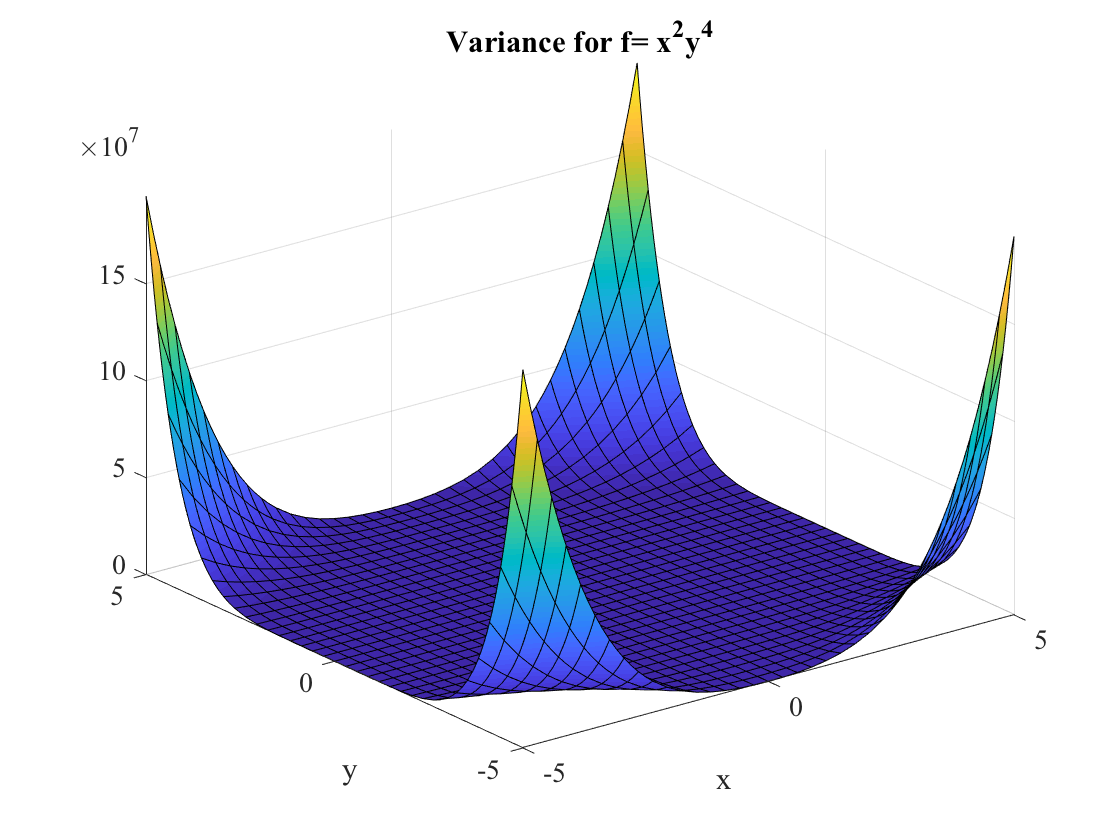

fsurf(subs(sigma2,[sigma_x,sigma_y],[1,1]))
title('Variance for f= x^2y^4')
xlabel('x');ylabel('y');

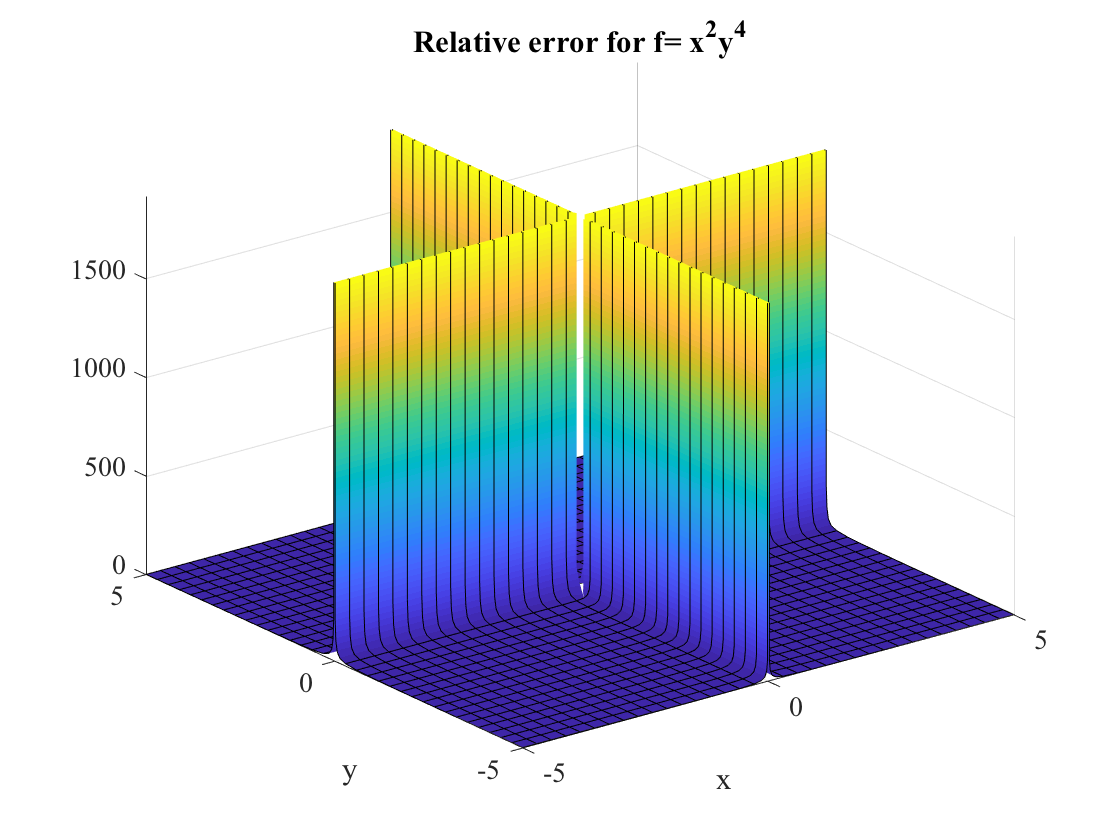

fsurf(subs(relative_error,[sigma_x,sigma_y],[1,1]))
title('Relative error for f= x^2y^4')
xlabel('x');ylabel('y');

## Simulate the error on a 1d function

Generate array R of normally distributed numbers for various mean values $\mu$ of x and standard deviations $\sigma$ using [normrnd](https://www.mathworks.com/help/stats/normrnd.html) by concatenating vectors with [cat](https://www.mathworks.com/help/matlab/ref/cat.html).

mu=[1:.1:10];% means
sigma0=0.1;
sigma = sigma0*ones(1,length(mu));% constant sigmas
nevents=100;% (the number of rows in R)
R=[]; % start with empty R
for ievent=1:nevents
    R=cat(1,R,normrnd(mu,sigma));% add row to R
end

Compute value of a function, say x^2 for each random value x.

f=R.^2;

Compute mean, std, and relative error of the function values for each distribution using columns of R.

fmean=mean(f,1);
fstd = std(f,1);
frelative_error = fstd./fmean

frelative_error =       0.24435      0.17972      0.16654      0.14542      0.12945      0.12446      0.12121      0.11718      0.11658       0.1046     0.096969      0.10771     0.085081     0.080763     0.083289     0.080929     0.072346     0.067542     0.065107      0.05785     0.066525     0.069788     0.075022     0.061479     0.055016      0.05144     0.052593     0.056636     0.050663     0.055475     0.047202     0.054887      0.05386     0.049578      0.04736     0.042675     0.043349      0.03847     0.040109     0.039834     0.041753     0.036789     0.043165     0.036486     0.034582     0.033987     0.038214     0.030743     0.032316     0.032682


We expect the relative error in f=x^2 to be twice the relative error in x by propagation of uncertainty, i.e. 2*sigma/mu. Plot the simulated relative error, expected value

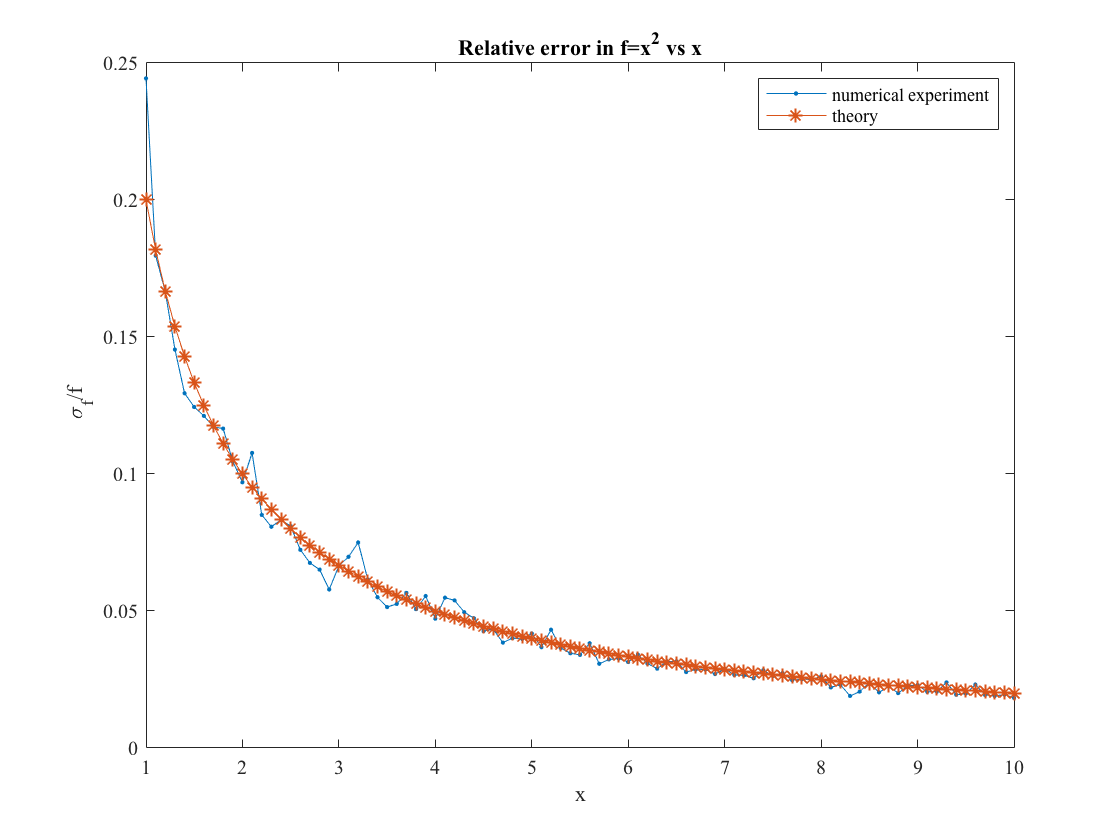

figure
plot(mu,frelative_error,'.-')
hold on
plot(mu,2*sigma0./mu,'*-')
title('Relative error in f=x^2 vs x')
xlabel('x');ylabel(' \sigma_f/f')
legend('numerical experiment','theory')